# Classification of a 4-class problem with a multilayer perceptron

The exercise demonstrates an application of a multilayer perceptron for solving the classification problem, consisting of 4 clusters of input data, representing 4 output classes.

The data consist of 4 clusters (a, b, c, d), defined in 2-dimensional input space. 

The task is to define a neural network (multilayer perceptron) for the classification of an arbitrary point in the 2-dimensional space into one of the classes (A, B, C, D).

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Define 4 clusters of input data

close all, clear all, clc, format compact

Define the number of samples to train the neural network classifier and the offset between the clusters of data. Training is easier with a large offset (> 0.6) and more difficult with a smaller offset (0.5 - 0.6) due to the close boundaries between the classes. A very small offset (< 0.5) defines overlapping classes and a difficult classification problem that still can be solved by a neural network.

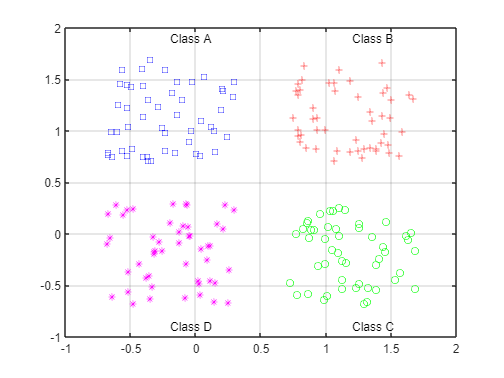

Nclass =50; % number of samples of each class
offset =0.7; % offset between classes

% define clusters of data
a = [rand(1,Nclass)-offset; rand(1,Nclass)+offset];
b = [rand(1,Nclass)+offset; rand(1,Nclass)+offset];
c = [rand(1,Nclass)+offset; rand(1,Nclass)-offset];
d = [rand(1,Nclass)-offset; rand(1,Nclass)-offset];

% plot classes
plot(a(1,:),a(2,:),'bs')
hold on
grid on
plot(b(1,:),b(2,:),'r+')
plot(c(1,:),c(2,:),'go')
plot(d(1,:),d(2,:),'m*')
% text labels for classes 
text(.5-offset,.5+2*offset,'Class A')
text(.5+offset,.5+2*offset,'Class B')
text(.5+offset,.5-2*offset,'Class C')
text(.5-offset,.5-2*offset,'Class D')

Plot data (4 clusters belonging to 4 classes)

## Prepare inputs & outputs for network training

Data from 4 clusters are collected into 4 classes of inputs. Outputs are encoded using two binary outputs (-1, +1).

% define inputs (combine samples from all four classes)
P = [a b c d];

% coding (+1/-1) of 4 separate classes (A, B, C, D)
A = [-1 -1 -1 +1]';
B = [-1 -1 +1 -1]';
D = [-1 +1 -1 -1]';
C = [+1 -1 -1 -1]';

% define targets
T = [repmat(A,1,length(a)) repmat(B,1,length(b)) ...
     repmat(C,1,length(c)) repmat(D,1,length(d)) ];

## Create and train a multilayer perceptron

Built-in MATLAB function 'feedforwardnet' is used to construct the multilayer perceptron.

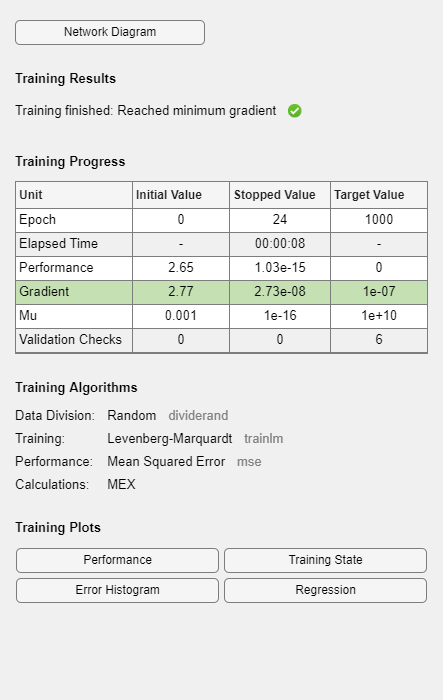

num_first_hidden_layer =6; % number of neurons in the first hidden layer
num_second_hidden_layer =4; % number of neurons in the first hidden layer

% create a neural network
net = feedforwardnet([num_first_hidden_layer num_second_hidden_layer]);

% training parameters
net.divideParam.trainRatio = 0.7; % training set [%]
net.divideParam.valRatio   = 0.15; % validation set [%]
net.divideParam.testRatio  = 0.15; % test set [%]

% train a neural network
[net,tr,Y,E] = train(net,P,T);

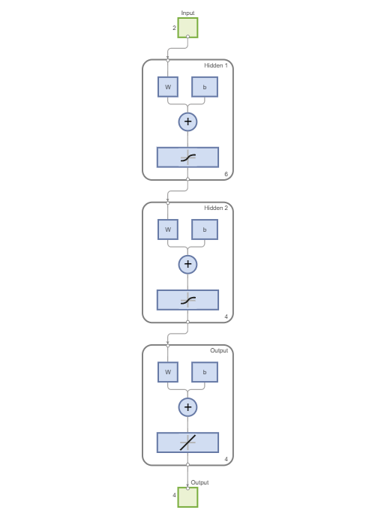

% show network
view(net)

## Evaluate network performance and plot results

Evaluate network performance by calculating the classification accuracy. 

% evaluate performance: decoding network response
[m,i] = max(T); % target class
[m,j] = max(Y); % predicted class
N = length(Y);  % number of all predictions

Calculate classification accuracy:


$$\textrm{classification}\;\textrm{accuracy}=\frac{\textrm{number}\;\textrm{of}\;\textrm{correct}\;\textrm{predictions}}{\textrm{total}\;\textrm{number}\;\textrm{of}\;\textrm{predictions}}$$


% calculate classification accuracy
correct_predictions = length(find(i==j));
classification_accuracy = correct_predictions/N

classification_accuracy = 1

Compare the targets (different colurs for each of 4 network outputs) with the network response. Ideally, they should be equal (or at least very similar). 

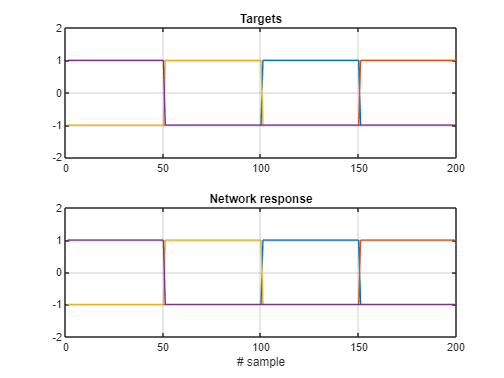

% plot targets and network response
figure;
subplot(211)
plot(T')
title('Targets')
ylim([-2 2])
grid on 
subplot(212)
plot(Y')
title('Network response')
xlabel('# sample')
ylim([-2 2])
grid on

## Plot classification result for the complete input space

The decision boundaries, representing how the trained network classifies the input data, are shown in 4 colors (each representing one of 4 classes).

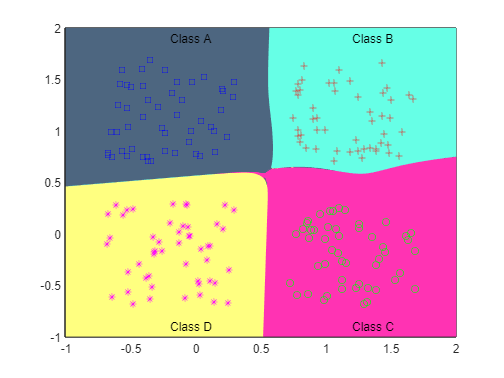

% generate a grid
span = -1:.01:2;
[P1,P2] = meshgrid(span,span);
input_grid = [P1(:) P2(:)]';

% simulate neural network on a grid
output_grid = net(input_grid);

% plot classification regions based on MAX activation
figure(1)
m = mesh(P1,P2,reshape(output_grid(1,:),length(span),length(span))-5);
set(m,'facecolor',[1 0.2 .7],'linestyle','none');
hold on
m = mesh(P1,P2,reshape(output_grid(2,:),length(span),length(span))-5);
set(m,'facecolor',[1 1.0 0.5],'linestyle','none');
m = mesh(P1,P2,reshape(output_grid(3,:),length(span),length(span))-5);
set(m,'facecolor',[.4 1.0 0.9],'linestyle','none');
m = mesh(P1,P2,reshape(output_grid(4,:),length(span),length(span))-5);
set(m,'facecolor',[.3 .4 0.5],'linestyle','none');
view(2)

% close all windows
close all force

## Suggestions

Try to expand the range of neural network parameters and see how the resulting network performs. 

Suggestions to experiment:

- Remove the second hidden layer (num_second_hidden_layer = [ ];) and see the result.

- Experiment with various selections of training parameters, e.g. [0.7 0.15 0.15], [1 0 0], [0.4 0.3 0.3]

- Try different training algorithms, such as: `'trainlm',` `'traingd', 'traincgb', ...` (see the [Documentation on 'feedforwardnet'](https://www.mathworks.com/help/deeplearning/ref/feedforwardnet.html))

**Further suggestion**

Try alternative coding of outputs:

% A=1; B=2; C=3; D=4;

And evaluate network performance with:

% figure, plot(T),hold on, grid on, plot(Y,'--'), legend('target','prediction')
% correct_predictions = length(find(round(Y)==T));
% classification_accuracy = correct_predictions/length(T)

## PowerPoint presentation

[NN4a_Backpropagation.pptx](matlab:open('./NN4a_Backpropagation.pptx'))